%% General Setup
N = 300;
lims = [0, floor(N/2)];
n = linspace(lims(1), lims(2), N);

## Input signal

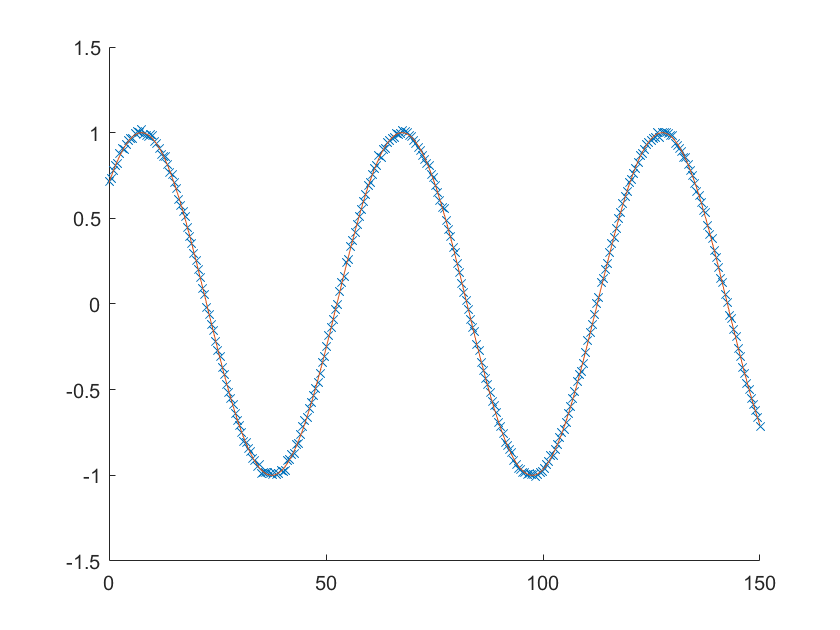

sigma_v2 = 1e-1; % Noise variance 
theta = pi/4; % Phase constant 
z = sin((2*pi/60)*n + theta); % Input signal: z(n)

% Signal with additive white Gaussian noise (AWGN): d(n) = z(n) + v(n)
v = randn(1,N)*sqrt(sigma_v2);
d = z + v;

figure();
scatter(n,d,"x");
hold on
plot(n,z);

legend({'d','z'})
hold off

## LMS Filter

L = 30;  % Filter Length/Number of coefficients
mu = 1e-2;
lms_nonnormalized = dsp.LMSFilter(L,'StepSize',mu,...
    'Method','LMS');
[aa ,error_1, wts] = lms_nonnormalized(z',d');
[mmse,emse,meanW,mse,traceK] = msepred(lms_nonnormalized,z',d',L);
error_1_dB = 10*log10(error_1.^2); 
figure();
plot(n,error_1_dB)
figure();
plot(n, d, n, aa,'LineStyle', ':');
figure(); 
plot(meanW);

script